load accidents

x = hwydata(: , 14); % population of states
y = hwydata(: , 4); % accidents per state

format long

b1 = x\y; % b1 is the slope of regresion coefficient. The liniar relation is: y = b1 * x

yCalc1 = b1 * x; %  calculate the accidents per state "yCalc" from "x" using the relation. 

scatter(x,y)
hold on 
plot(x,yCalc1)
ylabel("Population of state")
xlabel("Fatal traffic accidents per state")
title("Liniar regressin relation between accidents & population")
grid on
tbl = table(x,y)

tbl = 51×2 table
       x        y 
    _______    ___

     493782    164
     572059     43
     608827     98
     626932    101
     642200    100
     754844    197
     783600    134
     902195    229
    1048319     83
    1211537    142
    1235786    171
    1274923    194
    1293953    260
    1711263    254
    1808344    411
    1819046    521


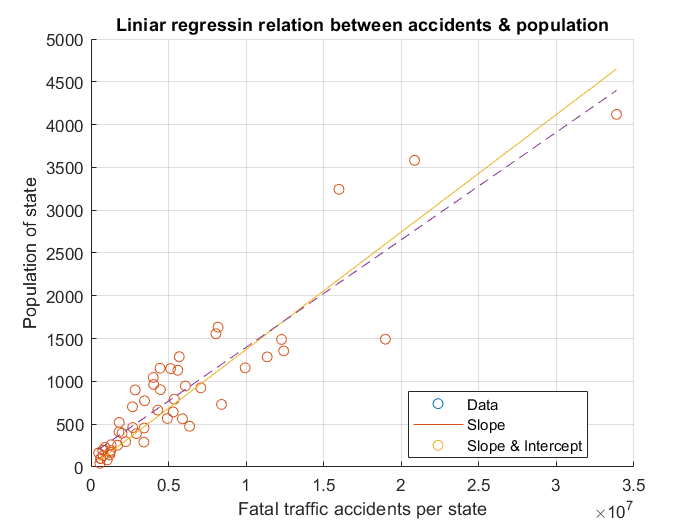



% Improve the fit by including a y-intercept as y = bo - b1*x
% Calculate bo by padding x with a column of ones and using the \ operator.

X = [ones(length(x),1) x];
b = X\y;


yCalc2 = X*b;
plot(x,yCalc2, '--')
legend("Data", "Slope", "Slope & Intercept", "Location" , "best")


bb = regress(y, X);

